# IHC recordings - tecta-cre;Cx26flfl with P2ry1 inhibition

% room temp, 6K ACSF
defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\Inner HCs 6K'

defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\Inner HCs 6K'

cd(defaultDir);


% Adjacent to IHCs
[tectaCx261 time1] = loadPclampData('2019_09_05_0006_adjusted2.abf');

** abfload
opening 2019_09_05_0006_adjusted2.abf..
data were acquired in gap-free mode


[tectaCx262 time2] = loadPclampData('2020_07_17_0001_baseline.abf');

** abfload
opening 2020_07_17_0001_baseline.abf..
data were acquired in gap-free mode


[tectaCx263 time3] = loadPclampData('2020_07_17_0009_baseline.abf');

** abfload
opening 2020_07_17_0009_baseline.abf..
data were acquired in gap-free mode


[tectaCx264 time4] = loadPclampData('2020_07_17_0015_baseline.abf');

** abfload
opening 2020_07_17_0015_baseline.abf..
data were acquired in gap-free mode


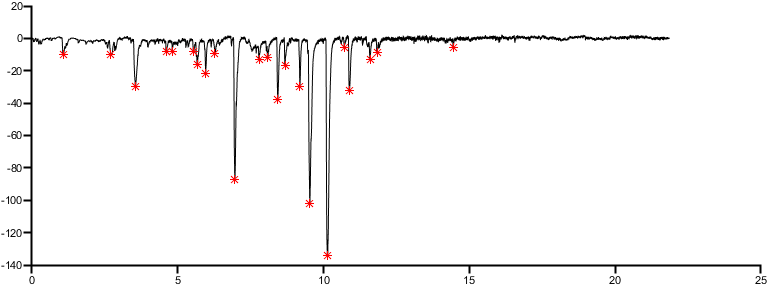

preFreq1 = 2.2000

postFreq1 = 0.2000

preAmp1 = -36.6899

postAmp1 = -5.7435


[preFreq1,postFreq1,preAmp1,postAmp1] = freqAmpIHC2(tectaCx261,time1,12.5) %1.5 minute wash in

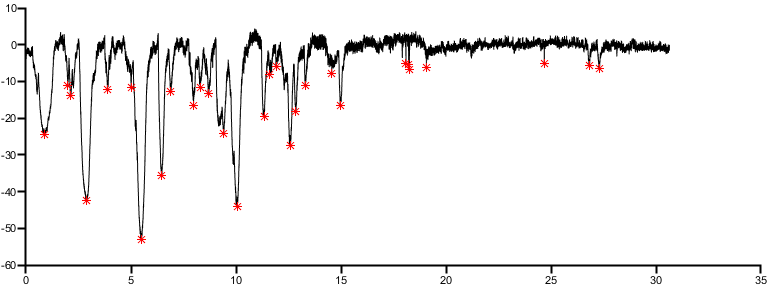

preFreq2 = 1.8000

postFreq2 = 0.8000

preAmp2 = -17.6284

postAmp2 = -5.8847

[preFreq2,postFreq2,preAmp2,postAmp2] = freqAmpIHC2(tectaCx262,time2,15)

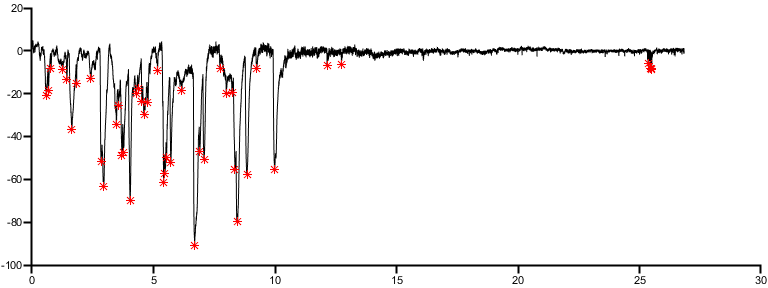

preFreq3 = 2.4000

postFreq3 = 0.4000

preAmp3 = -42.5526

postAmp3 = -6.5434

[preFreq3,postFreq3,preAmp3,postAmp3] = freqAmpIHC2(tectaCx263,time3,11)

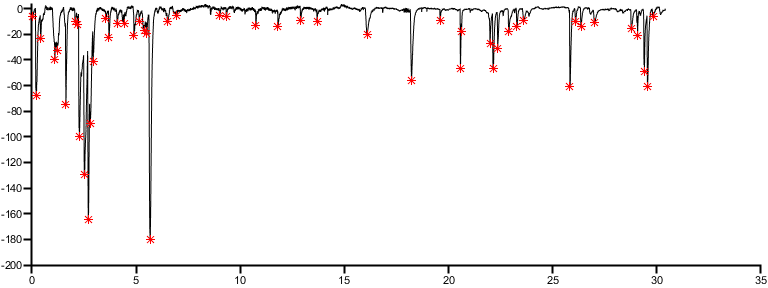

preFreq4 = 3.6000

postFreq4 = 0.8000

preAmp4 = -47.9799

postAmp4 = -9.6552

[preFreq4,postFreq4,preAmp4,postAmp4] = freqAmpIHC2(tectaCx264,time4,7)


preF = [preFreq1,preFreq2,preFreq3,preFreq4];
postF = [postFreq1,postFreq2,postFreq3,postFreq4];
preA = abs([preAmp1,preAmp2,preAmp3,preAmp4]);
postA = abs([postAmp1,postAmp2,postAmp3,postAmp4]);


% plots
conditions = {'baseline','+MRS2500'};
ylbl1 = 'Events per minute';
ylbl2 = 'Mean amplitude (-pA)';
ylbl3 = 'normalized charge (pA*S)';
dim = [1 2];
[fig1 h p1] = compare2_2(preF,postF,conditions,ylbl1,dim);

    0.0132



p1 

p1 = 0.0132

ylim([0 5]);
%export_fig('.\EPS Panels\IHCMRSFreq.eps',gcf);  

[fig2 h p2] =compare2_2(preA,postA,conditions,ylbl2,dim);

    0.0168



p2

p2 = 0.0168

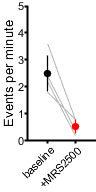

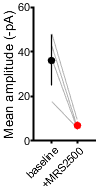

ylim([0 60]);
 
 
 subP = handleTheSubplot({fig1,fig2},[1 2]);

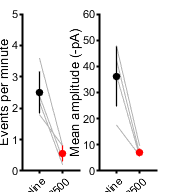

figQuality(subP,gca,[1.8 2])

 
 [CorrP CorrA h] = fdr_BH([p1,p2],0.05)

CorrP =     0.0168    0.0168


CorrA =     0.0250    0.0500


h = 2×1 logical array
   1
   1


% pretty example plot

% tecta-cre; cx26 fl/fl close to IHC

[tectaCx261 time1] = loadPclampData('2019_09_05_0006.abf');

** abfload
opening 2019_09_05_0006.abf..
data were acquired in gap-free mode


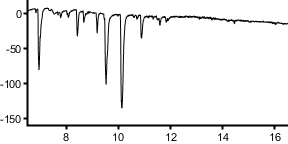

figure;
tectacx = medfilt1(tectaCx261,250);
plot(time1()/60,tectacx(),'k','LineWidth', 1)
ylim([-160 20]);
xlim([6.5 16.5])
figQuality(gcf,gca,[3 1.5])


[tectaCx261 time1] = loadPclampData('2020_07_17_0009.abf');

** abfload
opening 2020_07_17_0009.abf..
data were acquired in gap-free mode


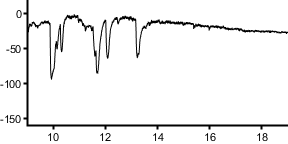

figure;
tectacx = medfilt1(tectaCx261,250);
plot(time1()/60,tectacx(),'k','LineWidth', 1)
ylim([-100 20]);
xlim([9.5 19.5])
figQuality(gcf,gca,[3 1.5])